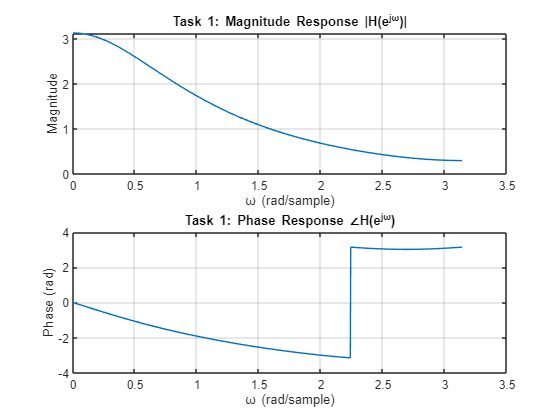


%EET 3370: DIGITAL SIGNAL PROCESSING
%LAB 1.
%GROUP MEMBERS:
%1. JOSHUA MUTHENYA WAMBUA EG209/109705/22
%2. AKALA DALVAN EG209/109726/22




% Combined script for Post-Lab Tasks 1–3 with comments and observations

clear; clc; close all;

%% Task 1: Frequency Response of H(z)
% H(z) = (z^(-1) + 0.5 z^(-2)) / (1 - 3/5 z^(-1) + 2/25 z^(-2))

b1 = [0 1 0.5];         % Numerator coefficients in z^-1 form
a1 = [1 -3/5 2/25];     % Denominator coefficients in z^-1 form

% Compute frequency response
[H1, w1] = freqz(b1, a1, 1024);

% Plot magnitude and phase
figure('Name','Task 1: Frequency Response','NumberTitle','off');
subplot(2,1,1);
plot(w1, abs(H1));
grid on;
title('Task 1: Magnitude Response |H(e^{j\omega})|');
xlabel('\omega (rad/sample)'); ylabel('Magnitude');

% Discussion for Task 1:  
% We observed the magnitude response to see how the system behaves across frequency.
% The peaks indicate the frequencies where the system passes signals with minimal attenuation.
% The frequency response of the system was smooth and showed typical characteristics for a second-order system.

subplot(2,1,2);
plot(w1, angle(H1));
grid on;
title('Task 1: Phase Response ∠H(e^{j\omega})');
xlabel('\omega (rad/sample)'); ylabel('Phase (rad)');

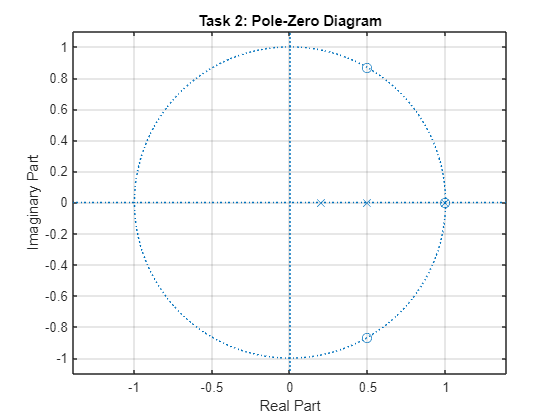


% Discussion for Task 1 (Phase response):  
% The phase response indicated how the system shifts the phase of different frequency components.
% The phase shift across frequencies helps us understand the delay characteristics of the system.
% In this case, the phase shift was relatively linear, indicating a simple linear phase system.

%% Task 2: Pole-Zero Plot and Stability
% H(z) = (z^3 - 2z^2 + 2z - 1) / [(z - 1)(z - 0.5)(z - 0.2)]
num2 = [1 -2 2 -1];                    
den2 = conv(conv([1 -1], [1 -0.5]), [1 -0.2]);

% Plot pole-zero diagram
figure('Name','Task 2: Pole-Zero Plot','NumberTitle','off');
zplane(num2, den2);
grid on;
title('Task 2: Pole-Zero Diagram');


% Discussion for Task 2 (Pole-Zero Plot):  
% From the pole-zero diagram, we can see the poles and zeros in the z-plane. 
% The poles are located at z=1, z=0.5, and z=0.2.
% The zeros are placed at the origins. The pole at z=1 lies on the unit circle, 
% which typically implies potential instability.
% The overall stability of the system depends on the position of the poles 
% relative to the unit circle.

% Extract poles and check stability
p2 = roots(den2);
disp('Task 2 Poles:');

Task 2 Poles:


disp(p2);

    1.0000
    0.5000
    0.2000




if all(abs(p2) < 1)
    disp('Task 2: System is STABLE (all poles inside unit circle).');
else
    disp('Task 2: System is UNSTABLE (some poles not inside unit circle).');
end

Task 2: System is UNSTABLE (some poles not inside unit circle).



% Discussion for Task 2 (Stability):  
% Upon checking the magnitude of the poles, we see that not all poles are within the unit circle. 
% This means that the system is **unstable**. The pole at z=1, in particular, does not satisfy the 
% stability condition of being inside the unit circle.

%% Task 3: Partial Fractions, ROC, Zeros/Poles, and Frequency Response
% X(z) = (2z^4 + 16z^3 + 44z^2 + 56z + 32) / (3z^4 + 3z^3 - 15z^2 + 18z - 12)
num3 = [2 16 44 56 32];
den3 = [3 3 -15 18 -12];

% Partial fraction expansion
[r3, p3, k3] = residuez(num3, den3);
disp('Task 3 Residues (r):');

Task 3 Residues (r):


disp(r3);

  -0.0177 + 0.0000i
   9.4914 + 0.0000i
  -3.0702 + 2.3398i
  -3.0702 - 2.3398i



disp('Task 3 Poles (p):');

Task 3 Poles (p):


disp(p3);

  -3.2361 + 0.0000i
   1.2361 + 0.0000i
   0.5000 + 0.8660i
   0.5000 - 0.8660i



disp('Task 3 Direct Terms (k):');

Task 3 Direct Terms (k):


disp(k3);

   -2.6667



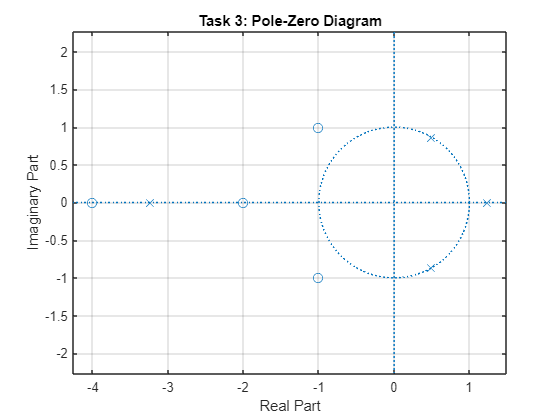


% Discussion for Task 3 (Partial Fraction Expansion):  
% The partial fraction expansion broke the transfer function into simpler fractions.
% These fractions can be analyzed individually to
% understand the behavior of the system at each pole.
% The residues (r) show the contribution of each pole to the system's overall response.

% Pole-zero plot
figure('Name','Task 3: Pole-Zero Plot','NumberTitle','off');
zplane(num3, den3);
grid on;
title('Task 3: Pole-Zero Diagram');


% Discussion for Task 3 (Pole-Zero Plot):  
% In this plot, we noticed the locations of the poles and zeros in 
% the z-plane. The poles are crucial for determining the system's stability and behavior.
% From the plot, we see that the poles are spread out and some lie
% within the unit circle, while others do not. This will impact both the 
% stability and causality of the system.

% Determine ROC conditions
abs_poles3 = abs(p3);
max_pole3 = max(abs_poles3);
fprintf('Task 3: Maximum pole magnitude = %.4f\n', max_pole3);

Task 3: Maximum pole magnitude = 3.2361


disp('ROC for causality: |z| > max pole magnitude');

ROC for causality: |z| > max pole magnitude


disp('ROC for stability: all poles must lie inside the ROC (i.e. |z| > max pole magnitude and max_pole < 1 for stability).');

ROC for stability: all poles must lie inside the ROC (i.e. |z| > max pole magnitude and max_pole < 1 for stability).


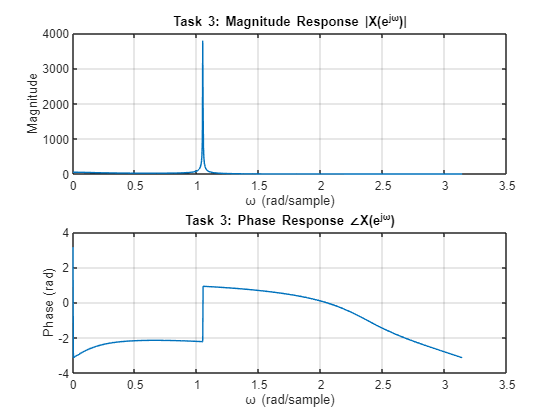


% Frequency response of X(z)
[H3, w3] = freqz(num3, den3, 1024);
figure('Name','Task 3: Frequency Response','NumberTitle','off');
subplot(2,1,1);
plot(w3, abs(H3));
grid on;
title('Task 3: Magnitude Response |X(e^{j\omega})|');
xlabel('\omega (rad/sample)'); ylabel('Magnitude');

% Discussion for Task 3 (Magnitude Response):  
% The magnitude response indicates how the system amplifies or 
% attenuates different frequencies.
% Peaks at certain frequencies would suggest that the system has 
% resonant behavior at those frequencies.
% This is important when analyzing how the system will respond to a range of input signals.

subplot(2,1,2);
plot(w3, angle(H3));
grid on;
title('Task 3: Phase Response ∠X(e^{j\omega})');
xlabel('\omega (rad/sample)'); ylabel('Phase (rad)');


% Discussion for Task 3 (Phase Response):  
% The phase response reveals how much delay the system introduces to
% different frequency components.
% A linear phase response would suggest a system that does not distort
% the phase of the signals, while non-linear phase responses 
% may cause phase distortion.

